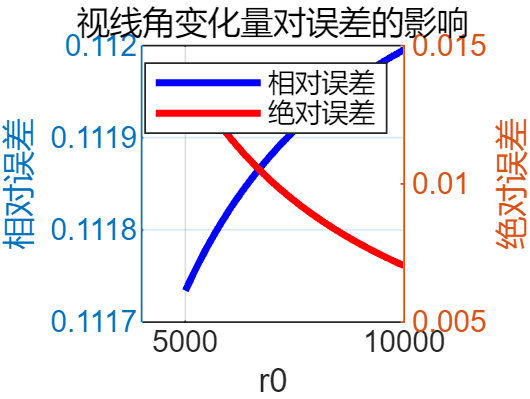

% 清空工作区，关闭所有图形窗口
clear; clc; close all;

% 执行其他三个脚本，数据将保存在工作区中
run('R0_up.mlx'); % 执行第一个脚本

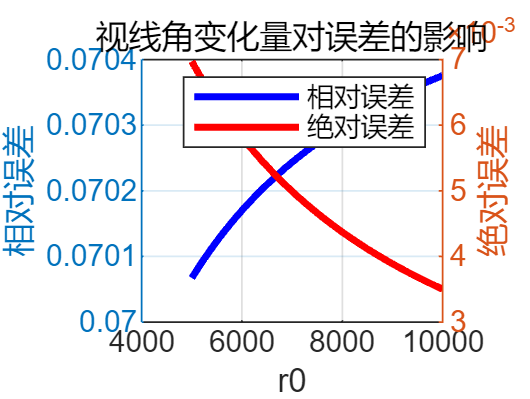

run('R0_mid.mlx'); % 执行第二个脚本

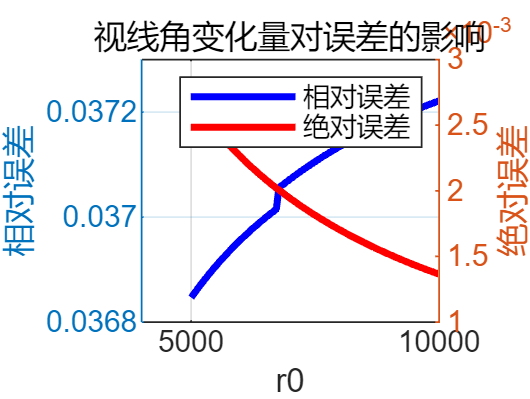

run('R0_down.mlx'); % 执行第三个脚本

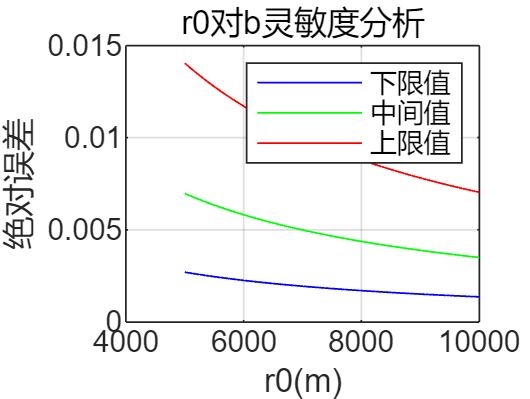



% 绘图：你可以选择在同一图上绘制不同的数据
figure;

plot(r0_down, absolute_error_down, 'b', 'DisplayName', '下限值');
hold on;
ylabel('绝对误差');
plot(r0_mid, absolute_error_mid, 'g', 'DisplayName', '中间值');
plot(r0_up, absolute_error_up, 'r', 'DisplayName', '上限值');

xlabel('r0(m)');
title('r0对b灵敏度分析');
grid on;
legend show;

hold off;